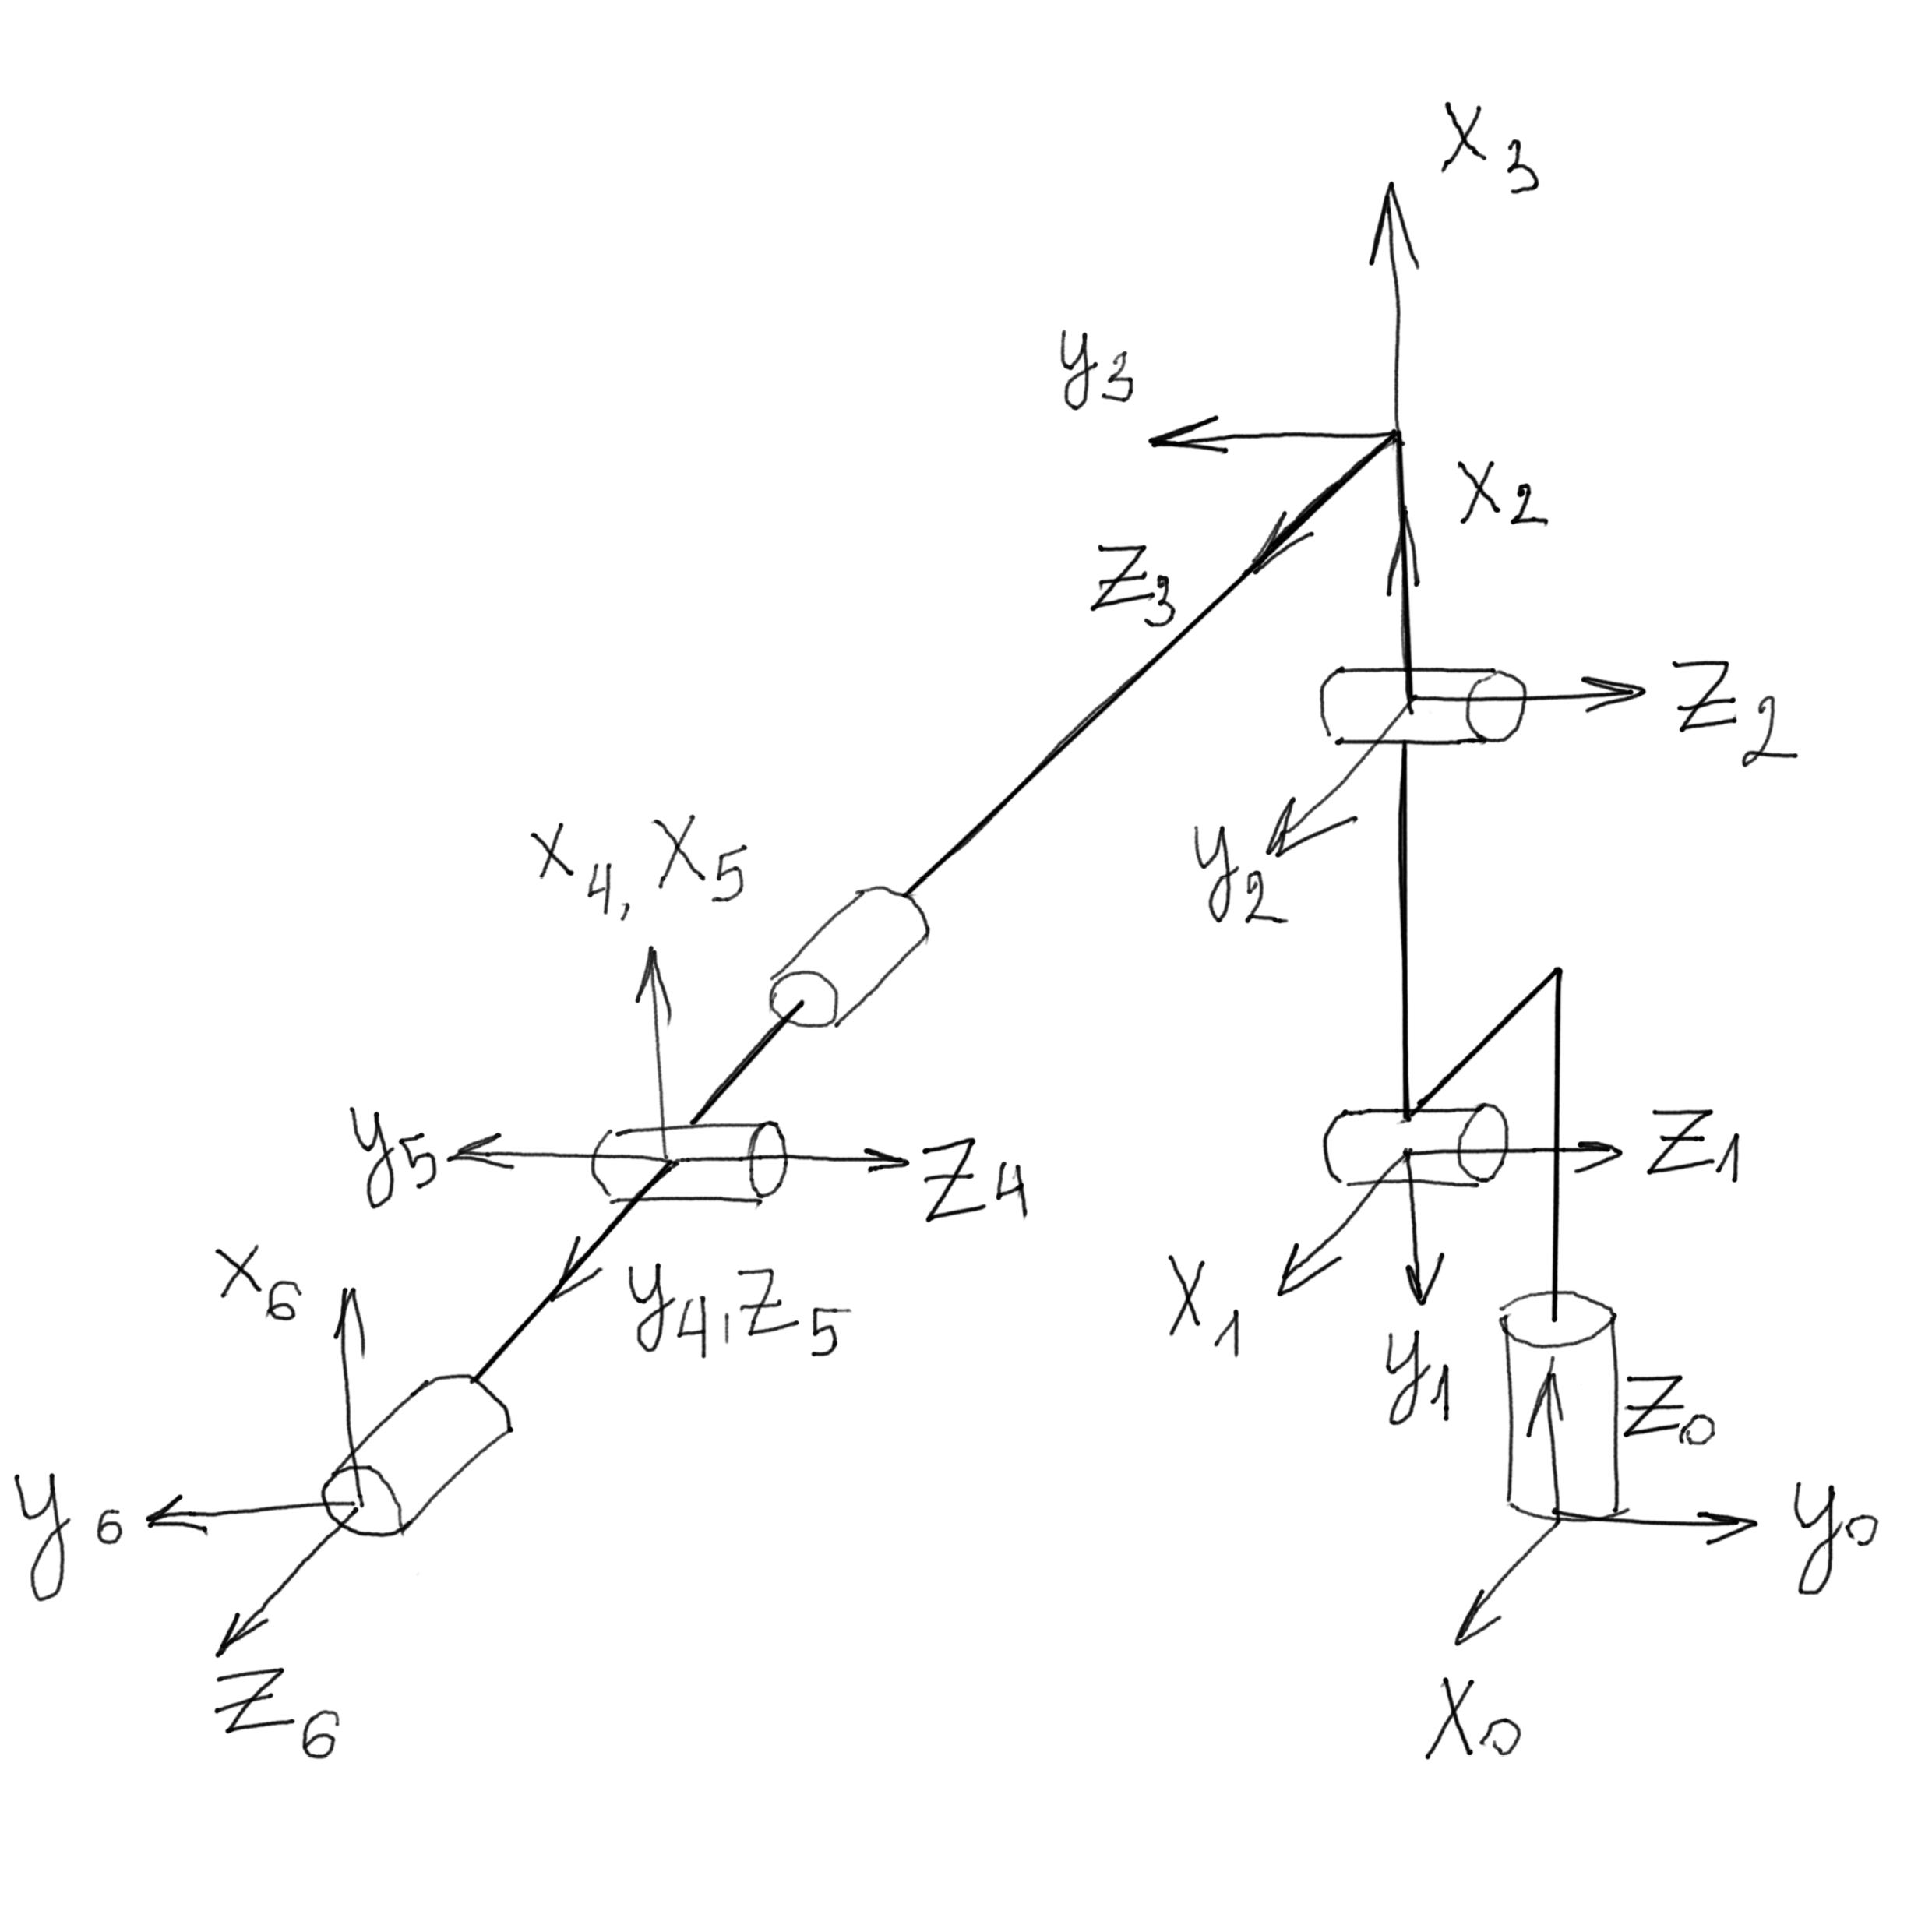

Get the forward kinematics

%% Define the forward kinematics

syms q1 q2 q3 q4 q5 q6 a1 a2 a4
H =  Rot_z(q1)*Tr_z(a1)*Rot_y(q2)*Tr_x(a2)*Rot_y(q3)*Tr_x(a4)*Rot_x(q4) * Rot_y(q5) * Rot_x(q6)

h = simplify (H)

%Rotation part

T4_5_6 = Rot_x(q4) * Rot_y(q5) * Rot_x(q6);
T4_5_6 = simplify(T4_5_6)

$$T4\_5\_6 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & 0\\ \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & 0\\ -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%Translation part

%Translation part
T0_1 = Rot_z(q1);
T1_2 =Tr_z(a1)*Rot_y(q2) ;
T2_3 = Tr_x(a2)*Rot_y(q3);
T3_4 = Tr_x(a4);
T0_4 = T0_1 * T1_2 * T2_3 * T3_4

$$T0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & a_{4}\,\sigma_{1}+a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{3}-\sigma_{2} & \cos\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-a_{4}\,\left(\sigma_{2}-\sigma_{3}\right)\\ -\sigma_{5}-\sigma_{4} & 0 & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & a_{1}-a_{4}\,\left(\sigma_{5}+\sigma_{4}\right)-a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{4}=\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{5}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}$$